# EXERCISE #3 : Bluetooth LE Network for Multi-stream Audio  

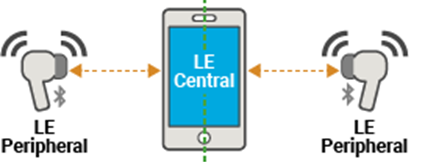

**In this exercise, you will:**

- Establish an Asynchronous Connection-Oriented (ACL) link and a Connected Isochronous Stream (CIS) connection 

- Model audio streaming at different bit rates

- Simulate and visualize packet communication and node state transitions over time

- Enable a Wireless Local Area Network (WLAN) Interferer and analyze its impact on performance

- Perform cleanup by closing previously opened windows and figures. 

- Initialize the random number generator for reproducibility

- Set the simulation time

- Initialize the network simulator

- Launch the wireless network viewer to visualize the network during simulation

rng(1,"twister");
clear all;
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows
networkSimulator = wirelessNetworkSimulator.init;
simulationTime = 0.5;
viewerObj = wirelessNetworkViewer();

#### Create a Bluetooth LE node, specifying the role as `"central"`.

source = bluetoothLENode("central", ...
    "Name","Central", ...
    Position=[0 0 0], ...
    TransmitterPower=-20);  
addNodes(viewerObj,source,Type="Source",Name=source.Name);

#### Create Bluetooth LE nodes, specifying the role as `"peripheral"` 

sink = bluetoothLENode("Peripheral", ...
    Position=[7 .15 0; 7 -0.15 0], ...
    Name=[" Left", " Right"], ...
    TransmitterPower=-20);
addNodes(viewerObj,sink,Type="Sink");

**Create a Bluetooth LE connection configuration **

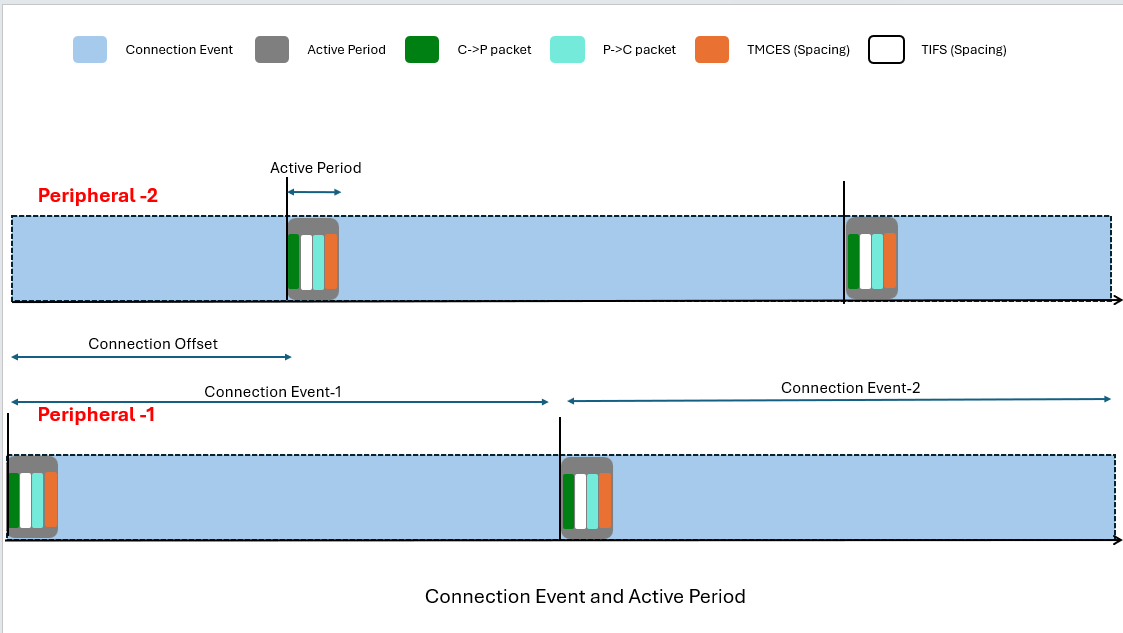

connectionInterval = 0.10;  % In seconds
phymode = "LE1M";
cfgConnection = bluetoothLEConnectionConfig(ConnectionInterval=connectionInterval, ...
    ActivePeriod=0.001, ...
    MaxPDU=27, ...
    PHYMode=phymode);

# Task 1/5: Create a Bluetooth LE CIS configuration 

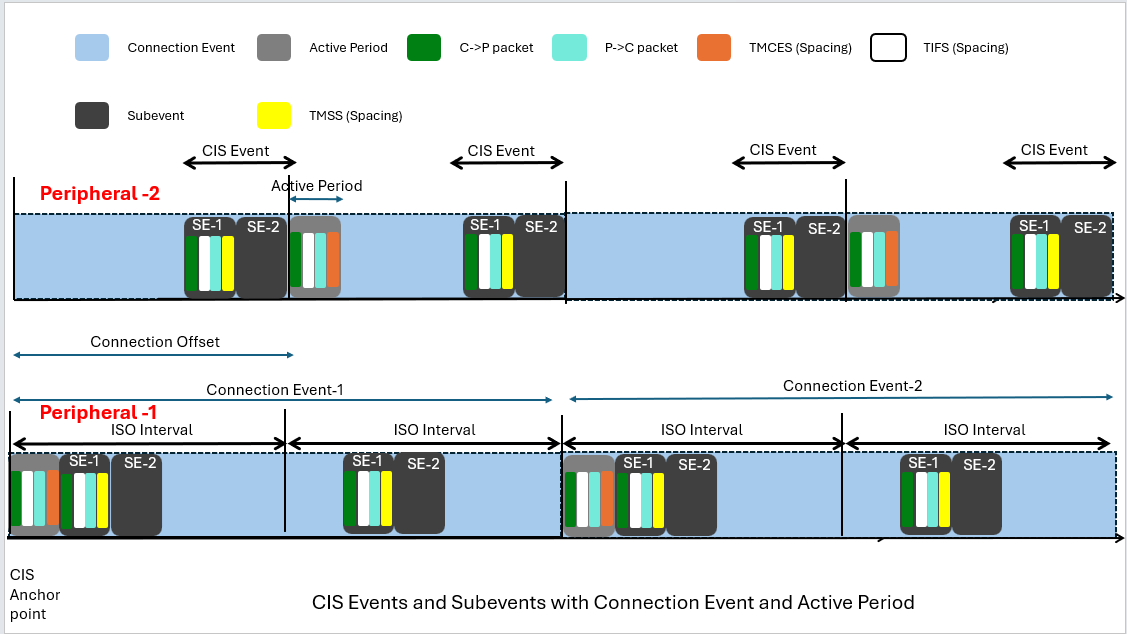

- **ISO Interval:** Time between the start of two consecutive Isochronous events.

- **Number of Subevents:** Count of time slots available inside each ISO Interval.

- **Burst Number (BN):** Number of unique payloads in a CIS event

- **Sub-Interval:** Time between the start of two consecutive subevents in CIS

Use bluetoothLECISConfig() function to set Bluetooth LE connection configuration parameters

Write configuration in a variable named "cfgCIS"

Hint: Type "doc bluetoothLECISConfig" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values to start with

- ISOInterval=0.050

- NumSubevents=2

- BurstNumber=1

- SubInterval= 0.005

%<Enter code here>
% cfgCIS = 

# Task 2/5: Configure the ACL and CIS connection between the source and the left sink

 Use configureConnection() function to configure the ACL and CIS connection 

**Hint:** Type "doc configureConnection" in the MATLAB Command Window and refer to the Syntax section. This function returns updated **ACL** and **CIS** configurations, so store them as:

[leftConnCfg, leftCISCfg] = ...

 Note : use the following values as arguments 

-  cfgConnection

-  source

-  sink(1)

-  CISConfig=cfgCIS 

cfgConnection.AccessAddress = "5DA44270";
cfgConnection.ConnectionOffset = 0; 
% <Enter code below>                                                                                      
% [leftConnCfg,leftCISCfg] = 

# Task 3/5: Configure the ACL and CIS connection between the source and the right sink

 Use configureConnection() function to configure the ACL and CIS connection 

**Hint:** Type "doc configureConnection" in the MATLAB Command Window and refer to the Syntax section. This function returns updated **ACL** and **CIS** configurations, so store them as:

[rightConnCfg,rightCISCfg] = ...

 Note : use the following values as arguments 

-  cfgConnection

-  source

-  sink(2)

-  CISConfig=cfgCIS 

cfgConnection.AccessAddress = "5DA44271";
cfgConnection.ConnectionOffset = 0.05; % In seconds
% <Enter code below> 
% [rightConnCfg,rightCISCfg] = 

#### Add the source and sink nodes to the wireless network simulator.

nodes = [source sink];
addNodes(networkSimulator,nodes);

#### Configure  Audio Traffic

Low Complexity Communication Codec (LC3)

dataRate = 312; % In kbps
traffic = networkTrafficOnOff(DataRate=dataRate,PacketSize=cfgCIS.MaxPDU,OnTime=Inf,OffTime=0);
plotTrafficPattern(simulationTime,traffic)

# Task 4/5: Add a traffic between source and leftSink  

Use addTrafficSource() function to add application traffic to the nodes  

Type "doc addTrafficSource" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- source

- traffic

- DestinationNode=sink(1)

- CISConfig=leftCISCfg

%<Enter code below>


# Task 5/5: Add audio traffic between source and right sink  

Use addTrafficSource() function to add application traffic to the nodes  

Type "doc addTrafficSource" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- source

- traffic

- DestinationNode=sink(2)

- CISConfig=rightCISCfg

%<Enter code below>


#### Enable the **Wireless Local Area Network (WLAN) Basic Service Set (BSS)**

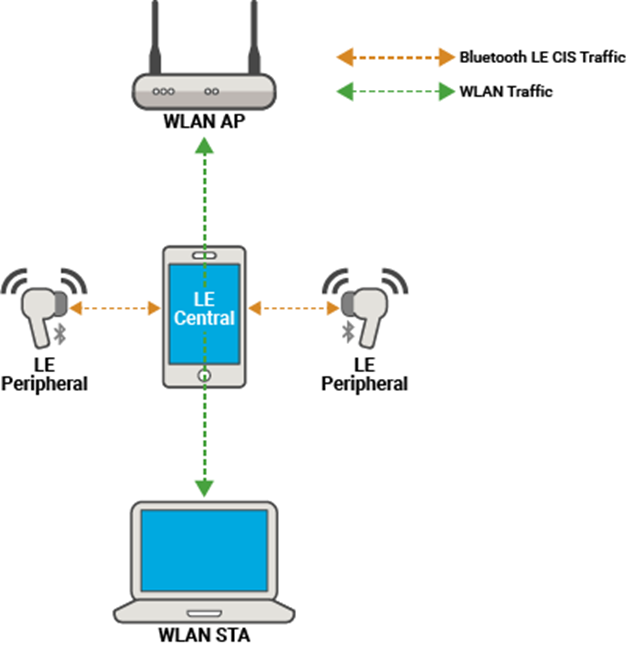

- Create Access Point (AP)

- Create Station (STA)

- Set up the WLAN network

- Add WLAN nodes to the network simulator

enableWLANInterference = true;
if enableWLANInterference
    apDeviceConfig = wlanDeviceConfig(Mode="AP",BandAndChannel=[2.4 7],TransmitPower=20,InterferenceModeling="overlapping-adjacent-channel");
    staDeviceConfig = wlanDeviceConfig(Mode="STA",BandAndChannel=[2.4 7],TransmitPower=20,InterferenceModeling="overlapping-adjacent-channel");
    wlanAPNode = wlanNode(DeviceConfig=apDeviceConfig,Name="AP",Position=[3 -2 0],MACModel="full-mac",PHYModel="full-phy");
    wlanSTANode = wlanNode(DeviceConfig=staDeviceConfig,Name="STA",Position=[3 2 0], MACModel="full-mac",PHYModel="full-phy");
    associateStations(wlanAPNode,wlanSTANode,BandAndChannel=[2.4 7],FullBufferTraffic="on");
    wlanNodes = [wlanAPNode wlanSTANode];
    addNodes(networkSimulator,wlanNodes)
    addNodes(viewerObj,wlanNodes,Type="WLAN");
end

#### Visualize Packet Transitions 

viewerObj = wirelessTrafficViewer;
addNodes(viewerObj,networkSimulator.Nodes);

**Enable PCAP capture**

packetCaptureObj = blePCAPWriter(Node=nodes,FileExtension="pcap");

**Run the Simulation **

run(networkSimulator,simulationTime);

#### Measure Network KPIs

leftSinkThroughput = kpi(source,sink(1),"throughput",Layer="LL")
rightSinkThroughput = kpi(source,sink(2),"throughput",Layer="LL")
delete(packetCaptureObj);

*Copyright 2025-2026 The MathWorks, Inc.*